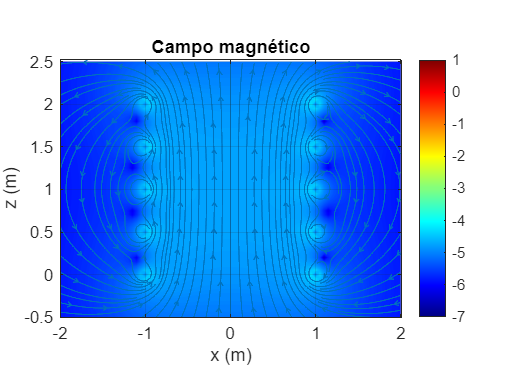

clc;
clear;
close all;

% Parámetros principales
nl = 6;           % Número de espiras
R = 1.5;          % Radio de las espiras (m)
sz = 1;           % Separación entre espiras (m)
I = 300;          % Corriente (A)
mo = 4*pi*1e-7;   % Permeabilidad magnética
N = 20;           % Número de puntos por espira
t_max = 7;        % Tiempo máximo de simulación (s)

% Condiciones iniciales para la trayectoria
z0 = 3.0;         % Posición inicial (m)
v0 = 0;           % Velocidad inicial (m/s)
dt = 0.001;       % Paso temporal (s)

% Parámetros físicos del dipolo
m = 0.1;          % Masa del imán (kg)
mag = 0.1;        % Momento magnético (A·m²)
gamma = 0.5;      % Coeficiente de fricción (N·s/m)
g = 9.81;         % Aceleración gravitacional (m/s²)

% Nombre del video de salida
nombre_video = 'freno_magnetico_simulacion';

codigo1_campo_magnetico_espiras();

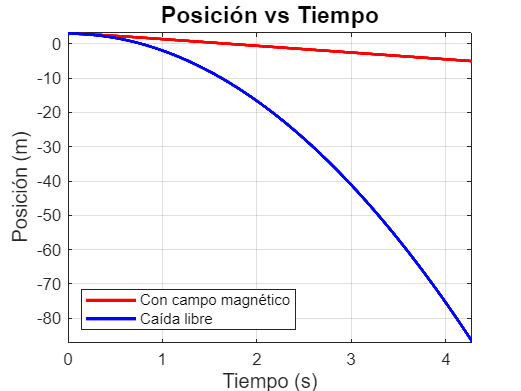

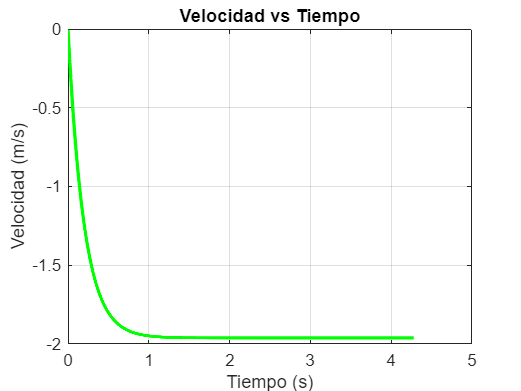


[t, zm, zmfree] = codigo2_trayectoria_completa(z0, v0, dt, t_max, nl, R, sz, I, mo, mag, gamma, m);

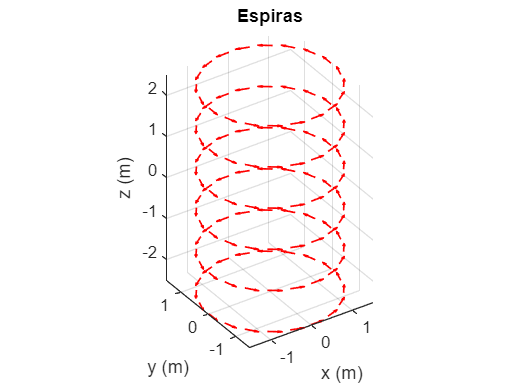


[Px, Py, Pz, dx, dy, dz] = generar_espiras(nl, N, R, sz);

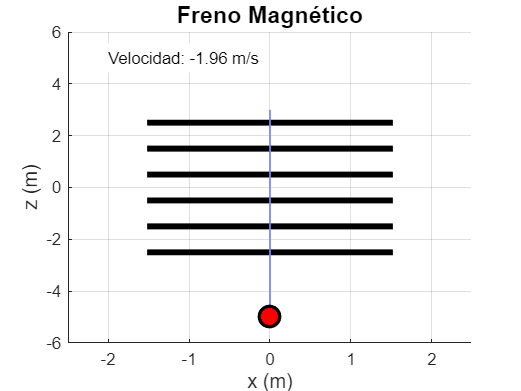

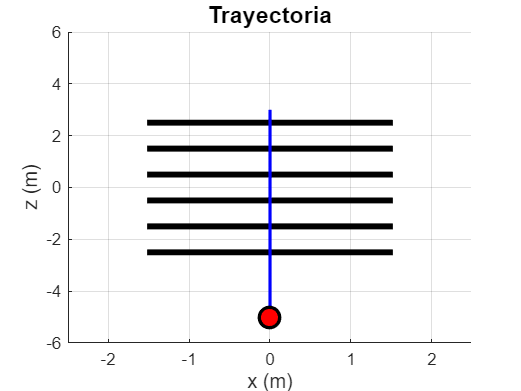


crear_animacion(zm, t, nombre_video, Pz, R);


%% Campo magnético
function codigo1_campo_magnetico_espiras()
    % Parámetros
    R = 1; % Radio de las espiras (m)
    N_theta = 100; % Número de puntos por espira
    N_loops = 5; % Número de espiras
    I = 10; % Corriente (A)
    spacing = 0.5; % Separación entre espiras (m)
    mu0 = 4*pi*1e-7; % Permeabilidad magnética del vacío
    
    % Coordenadas angulares para parametrizar las espiras
    theta = linspace(0, 2*pi, N_theta);
    
    % Generación de espiras
    z_pos = spacing * (0:N_loops-1); % Posiciones z de cada espira
    theta_grid = repmat(theta, 1, N_loops);
    z_grid = repelem(z_pos, N_theta);
    
    % Coordenadas cartesianas de todos los elementos de corriente
    x_total = R * cos(theta_grid);
    y_total = R * sin(theta_grid);
    z_total = z_grid;
    
    % Diferencias finitas para los elementos dl
    dx_total = gradient(x_total);
    dy_total = gradient(y_total);
    dz_total = gradient(z_total);
    
    % Malla de puntos donde calcular el campo
    xmin = -2; xmax = 2; xstep = 0.05;
    zmin = -0.5; zmax = (N_loops-1)*spacing + 0.5; zstep = 0.05;
    [x_grid, z_grid] = meshgrid(xmin:xstep:xmax, zmin:zstep:zmax);
    [nz, nx] = size(x_grid);
    Bx = zeros(nz, nx);
    Bz = zeros(nz, nx);
    
    % Cálculo del campo magnético en todos los puntos usando la ley de Biot-Savart
    for j = 1:length(x_total)
        r_source = [x_total(j); y_total(j); z_total(j)];
        dl = [dx_total(j); dy_total(j); dz_total(j)];
        
        % Vector r desde el elemento de corriente al punto de observación
        rx = x_grid - r_source(1);
        ry = - r_source(2); % y=0 en los puntos de evaluación (simetría)
        rz = z_grid - r_source(3);
        r_norm = sqrt(rx.^2 + ry.^2 + rz.^2);
        valid = r_norm > 1e-6; % Evitar división por cero cerca de la fuente
        
        % Producto cruz dl x r (solo componentes x y z necesarios)
        dBx = mu0*I/(4*pi) * (dl(2) * rz - dl(3) * ry) ./ (r_norm.^3);
        dBy = mu0*I/(4*pi) * (dl(3) * rx - dl(1) * rz) ./ (r_norm.^3); % no se usa
        dBz = mu0*I/(4*pi) * (dl(1) * ry - dl(2) * rx) ./ (r_norm.^3);
        
        % Sumar solo donde r_norm válido
        dBx(~valid) = 0;
        dBz(~valid) = 0;
        Bx = Bx + dBx;
        Bz = Bz + dBz;
    end
    
    % Magnitud del campo y transformación logarítmica para mejor visualización
    Bmag = sqrt(Bx.^2 + Bz.^2);
    Bmag_log = log10(Bmag + 1e-10);
    
    % Visualización
    figure;
    contourf(xmin:xstep:xmax, zmin:zstep:zmax, Bmag_log, 100, 'LineColor', 'none');
    colormap(jet);
    colorbar;
    hold on;
    streamslice(xmin:xstep:xmax, zmin:zstep:zmax, Bx, Bz, 2);
    title('Campo magnético');
    xlabel('x (m)');
    ylabel('z (m)');
    axis equal;
    grid on;
    caxis([-7, 1]); % Ajuste de escala de color
end

%% Trayectoria
function [t, zm, zmfree] = codigo2_trayectoria_completa(z0, v0, dt, t_max, nl, R, sz, I, mo, mag, gamma, m)
    % Generar campo Bz (simulado o calculado previamente)
    [Bz, z_axis] = calcular_campo_magnetico_trayectoria(nl, R, sz, I, mo);
    
    % Simulación con RK4
    [t, zm, zmfree] = simular_trayectoria(z0, v0, dt, t_max, Bz, z_axis, mag, gamma, m);
    
    % Visualización
    visualizar_resultados(t, zm, zmfree);
end

function [Bz, z_axis] = calcular_campo_magnetico_trayectoria(nl, R, sz, I, mo)
    % Eje z para calcular Bz
    z_axis = linspace(-5, 5, 1000);
    Bz = zeros(size(z_axis));
    
    % Cálculo simplificado de Bz en el eje
    for k = 1:length(z_axis)
        for i = 1:nl
            z_espira = -(nl-1)/2*sz + (i-1)*sz;
            r = sqrt(R^2 + (z_axis(k)-z_espira)^2);
            Bz(k) = Bz(k) + (mo*I*R^2) / (2*(r^2 + R^2)^(3/2));
        end
    end
end

function [t, zm, zmfree] = simular_trayectoria(z0, v0, dt, t_max, Bz, z_axis, mag, gamma, m)
    % Inicialización
    n_steps = ceil(t_max/dt);
    t = linspace(0, t_max, n_steps);
    zm = zeros(1, n_steps);
    zmfree = zeros(1, n_steps);
    vz = zeros(1, n_steps);
    
    zm(1) = z0;
    zmfree(1) = z0;
    vz(1) = v0;
    
    % Función anónima para la aceleración
    a_func = @(z,v) a_total(z, v, Bz, z_axis, mag, gamma, m);
    
    % Bucle de simulación
    cc = 1;
    for cc = 1:n_steps-1
        % Movimiento con fuerzas magnéticas (RK4)
        [zm(cc+1), vz(cc+1)] = rk4_step(zm(cc), vz(cc), dt, a_func);
        
        % Caída libre (solo gravedad)
        zmfree(cc+1) = z0 - 0.5*9.81*t(cc+1)^2;
        
        % Condición de parada
        if zm(cc+1) < -5 || abs(vz(cc+1)) < 1e-3
            break;
        end
    end
    
    % Recortar arrays si la simulación terminó antes
    t = t(1:cc+1);
    zm = zm(1:cc+1);
    zmfree = zmfree(1:cc+1);
end

function [z_next, v_next] = rk4_step(z, v, dt, a_func)
    % Runge-Kutta 4 orden
    k1z = v;
    k1v = a_func(z, v);
    
    k2z = v + 0.5*dt*k1v;
    k2v = a_func(z + 0.5*dt*k1z, v + 0.5*dt*k1v);
    
    k3z = v + 0.5*dt*k2v;
    k3v = a_func(z + 0.5*dt*k2z, v + 0.5*dt*k2v);
    
    k4z = v + dt*k3v;
    k4v = a_func(z + dt*k3z, v + dt*k3v);
    
    z_next = z + dt/6 * (k1z + 2*k2z + 2*k3z + k4z);
    v_next = v + dt/6 * (k1v + 2*k2v + 2*k3v + k4v);
end

function a = a_total(z, v, Bz, z_axis, mag, gamma, m)
    % Cálculo de la aceleración total
    delta = 0.005;
    
    % Gradiente de Bz
    Bz_forward = interp1(z_axis, Bz, z + delta, 'linear', 'extrap');
    Bz_backward = interp1(z_axis, Bz, z - delta, 'linear', 'extrap');
    dBz_dz = (Bz_forward - Bz_backward) / (2 * delta);
    
    % Fuerzas
    Fm = -mag * dBz_dz;       % Fuerza magnética
    Ff = -gamma * v;          % Fuerza de fricción
    Fg = -m * 9.81;           % Fuerza gravitacional
    
    % Aceleración total
    a = (Fm + Ff + Fg) / m;
end

function visualizar_resultados(t, zm, zmfree)
    % Crear figura
    figure('Position', [100, 100, 800, 600])
    
    % Gráfico de posición
    plot(t, zm, '-r', 'LineWidth', 2, 'DisplayName', 'Con campo magnético')
    hold on
    plot(t, zmfree, '-b', 'LineWidth', 2, 'DisplayName', 'Caída libre')
    grid on
 
    title('Posición vs Tiempo', 'FontSize', 14)
    xlabel('Tiempo (s)', 'FontSize', 12)
    ylabel('Posición (m)', 'FontSize', 12)
    legend('Location', 'southwest')
    xlim([0, max(t)])
    ylim([min([zm, zmfree])-0.5, max([zm, zmfree])+0.5])
    
    % Gradiente
    figure()
    vz = gradient(zm, t);
    plot(t, vz, '-g', 'LineWidth', 2)
    title('Velocidad vs Tiempo')
    xlabel('Tiempo (s)')
    ylabel('Velocidad (m/s)')
    grid on
end

function [Px, Py, Pz, dx, dy, dz] = generar_espiras(nl, N, R, sz)
    dtheta = 2*pi / N;
    ang = 0:dtheta:(2*pi - dtheta);
    s = 1;
    
    % Inicializar arrays
    Px = zeros(1, nl*N);
    Py = zeros(1, nl*N);
    Pz = zeros(1, nl*N);
    dx = zeros(1, nl*N);
    dy = zeros(1, nl*N);
    
    for i = 1:nl
        % Posiciones de los puntos
        Px(s:s+N-1) = R * cos(ang);
        Py(s:s+N-1) = R * sin(ang);
        Pz(s:s+N-1) = -(nl-1)/2*sz + (i-1)*sz;
        
        % Elementos diferenciales
        dx(s:s+N-1) = -Py(s:s+N-1) * dtheta;
        dy(s:s+N-1) = Px(s:s+N-1) * dtheta;
        s = s + N;
    end
    
    dz = zeros(1, N*nl);
    
    % Visualizar espiras
    figure(3);
    quiver3(Px, Py, Pz, dx, dy, dz, 0.5, '-r', 'LineWidth', 1);
    view(-34, 33);
    title('Espiras');
    xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
    axis equal;
    grid on;
end

%%%% FUNCIÓN PARA CREAR ANIMACIÓN - CORREGIDA %%%%
function crear_animacion(zm, tt, nombre_video, Pz_espiras, R)
    
    % Crear video writer
    writerObj = VideoWriter(nombre_video, 'MPEG-4');
    writerObj.FrameRate = 30;
    open(writerObj);
    
    % Parámetros de visualización
    z_range = [-6, 6];
    
    % Configurar figura para animación
    figure(100);
    set(gcf, 'Position', [100, 100, 800, 600]);
    
    % Determinar step para la animación (no todos los puntos)
    step = max(1, floor(length(zm)/300)); % Máximo 300 frames
    
    for i = 1:step:length(zm)
        clf;
        hold on;
        
        % Dibujar solenoide (espiras)
        z_coils = unique(Pz_espiras);
        for j = 1:length(z_coils)
            % Dibujar espira como rectángulo
            rectangle('Position', [-R, z_coils(j)-0.05, 2*R, 0.1], ...
                     'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'k', 'LineWidth', 2);
        end
        
        % Dibujar trayectoria hasta el punto actual
        if i > 1
            plot(zeros(1,i), zm(1:i), 'b-', 'LineWidth', 1, 'Color', [0.5 0.5 1]);
        end
        
        % Dibujar partícula (dipolo magnético)
        scatter(0, zm(i), 150, 'r', 'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 2);
        
        % Agregar flecha para mostrar dirección del momento magnético
        quiver(0, zm(i), 0, -0.2, 'r', 'LineWidth', 3, 'MaxHeadSize', 0.5);
        
        % Configurar ejes y etiquetas
        xlim([-2.5, 2.5]);
        ylim(z_range);
        xlabel('x (m)', 'FontSize', 12);
        ylabel('z (m)', 'FontSize', 12);
        title(sprintf('Freno Magnético', ...
              tt(i), zm(i)), 'FontSize', 14);
        grid on;
        
        % Agregar texto informativo
        if i > 1 && i < length(zm)
            velocidad = (zm(i) - zm(i-1))/(tt(i) - tt(i-1));
        else
            velocidad = 0;
        end
        text(-2, 5, sprintf('Velocidad: %.2f m/s', velocidad), ...
             'FontSize', 10, 'BackgroundColor', 'white');
        
        % Capturar frame
        frame = getframe(gcf);
        writeVideo(writerObj, frame);
        
        % Mostrar progreso
        if mod(i, 20) == 0
            fprintf('%.1f%% ', i/length(zm)*100);
        end
    end
    
    close(writerObj);
    
    % Mostrar frame final
    figure(101);
    clf;
    hold on;
    
    % Dibujar configuración final
    z_coils = unique(Pz_espiras);
    for j = 1:length(z_coils)
        rectangle('Position', [-R, z_coils(j)-0.05, 2*R, 0.1], ...
                 'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'k', 'LineWidth', 2);
    end
    
    % Dibujar trayectoria completa
    plot(zeros(size(zm)), zm, 'b-', 'LineWidth', 2);
    scatter(0, zm(end), 150, 'r', 'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 2);
    
    xlim([-2.5, 2.5]);
    ylim(z_range);
    xlabel('x (m)', 'FontSize', 12);
    ylabel('z (m)', 'FontSize', 12);
    title('Trayectoria', 'FontSize', 14);
    grid on;
end